# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 7: Sintonización de controladores PID en simulink

#### **Tarea 1: Diseño controlador PID en tiempo discreto**

Para el sistema de control de un sistema de dos depósitos, con planta dada por $G_p \left(s\right)=\frac{6}{\left(2s+1\right)\left(s+1\right)}$ en bucle abierto

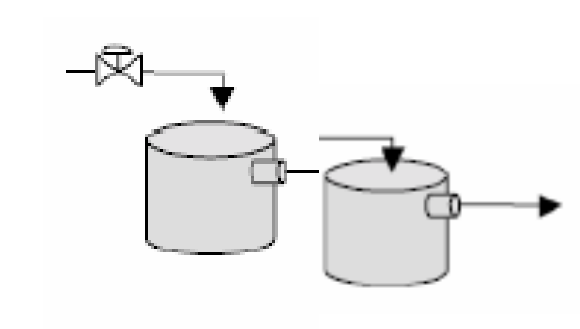

Se pide:

a) Diseñar un controlador PID digital, con tiempo de muestreo T=0.1, utilizando la herramienta **rtool** tal que se cumplan:

- SO<5%.

- 
$$t_{\textrm{estab}} <2s\ldotp$$


- error escalón nulo

% Tu código aquí
s = tf('s');
Gp = 6/((2*s+1)*(s+1));
Gp = zpk(Gp)

Gp =
 
        3
  -------------
  (s+1) (s+0.5)
 
Continuous-time zero/pole/gain model.
Model Properties


T = 0.1;
Gpz = c2d(Gp,T,'zoh'); %siempre lo hacemos con zoh la planta
Gpz = zpk(Gpz)

Gpz =
 
   0.014271 (z+0.9512)
  ---------------------
  (z-0.9512) (z-0.9048)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


C

C =
 
  6.7832 (z-0.957) (z-0.8813)
  ---------------------------
         (z-1) (z-0.1)
 
Name: C
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


%rltool(Gpz)
PIDz = pid(C)

PIDz =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 1.18, Ki = 0.385, Kd = 0.623, Tf = 0.111, Ts = 0.1
 
Name: C
Sample time: 0.1 seconds
Discrete-time PIDF controller in parallel form.
Model Properties


`Resultado esperado:`

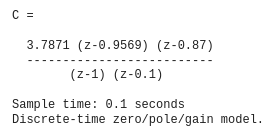

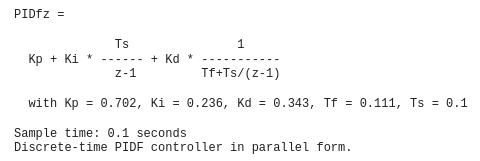

b) Implementar el sistema de control diseñado en SIMULINK utilizando el bloque PID de SIMULINK considerando el efecto del filtro derivativo con N variable, obteniendo la respuesta ante pulso de amplitud +5,-5 de duración de 5s y comentar las diferencias en función de N

% Tu código aquí

`Resultado esperado:`

x

C)  Añadir en el ploque PID una saturación de (+10,-10) a la acción de control y observar el efecto en la respuesta ante el pulso de referencia. Paliar dicha situación incluyendo el efecto anti-windup con valores variables de constante de tiempo $T_t$, $\left(K_b =\frac{1}{T_t }\right)$

% Pega una captura de tu modelo simulink aqui

`Resultado esperado:`

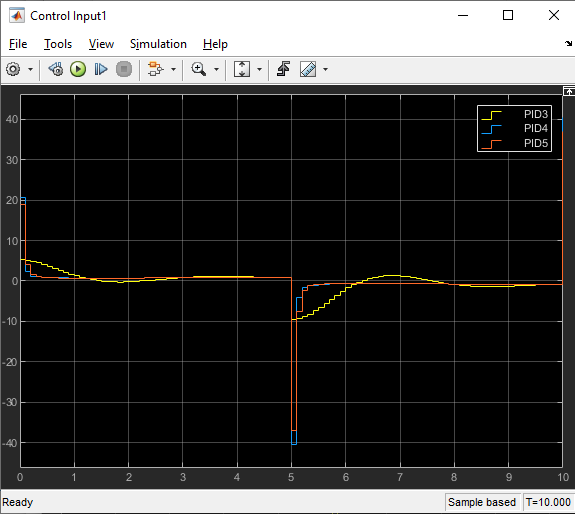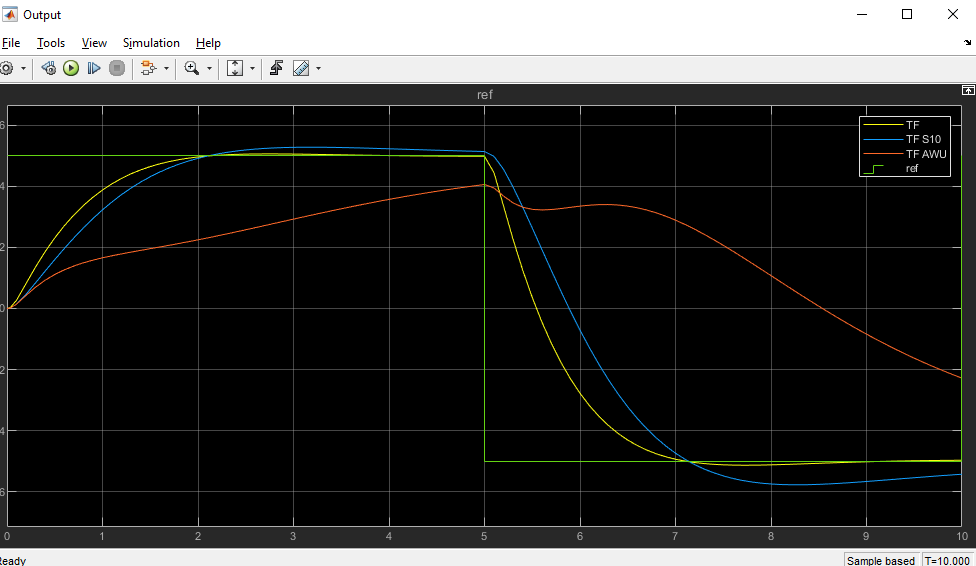

#### Tarea 2: Discretizacion de controlador PID continuo

El sistema de control de la figura muestra un control de velocidad PID que actúa sobre un motor CC, con $G_p \left(s\right)=\frac{0\ldotp 01}{0\ldotp 005s^2 +0\ldotp 06s+0\ldotp 1001}$

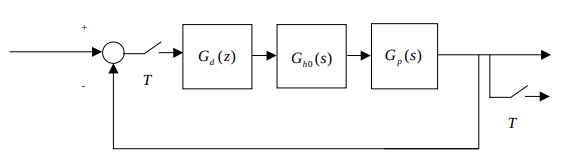

Asumiendo valores de Con $K_p$=70, $K_i$=40 y $K_d =5$. para el PID digital, y aplicando el método de discretización trapezoidal (bilineal) para el PID, con un T=0.01, implementar el sistema de control PID en SIMULINK añadiendo el filtro derivativo discretizado con N=100 también con el método trapezoidal y observar la respuesta en presencia de limitación de acción de control dgital (-15+15) y efecto antiwindup. Además observar el efecto del cambio del T en el sistema de control ya ajustado a valores de T=0.1 y T=0.5.

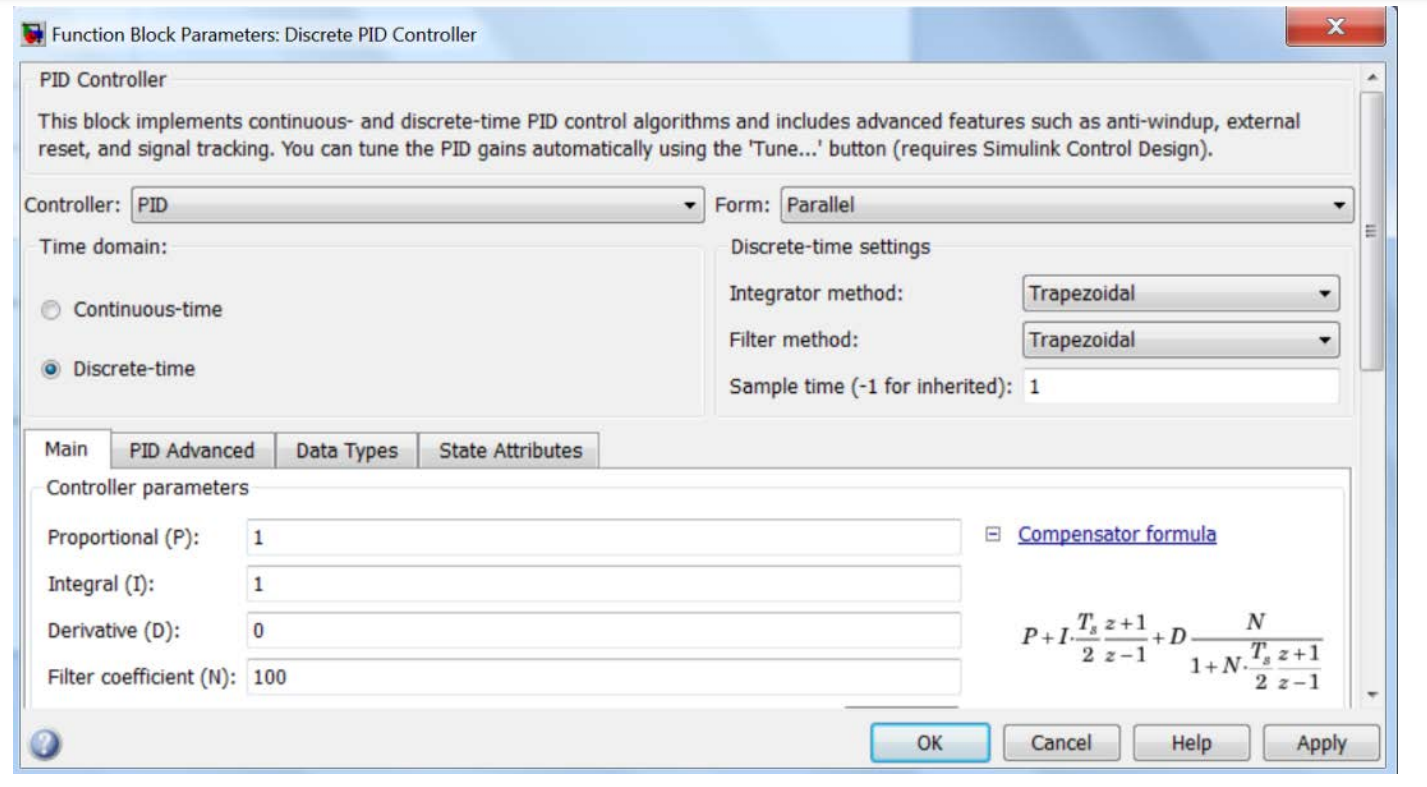

`Resultado esperado:`

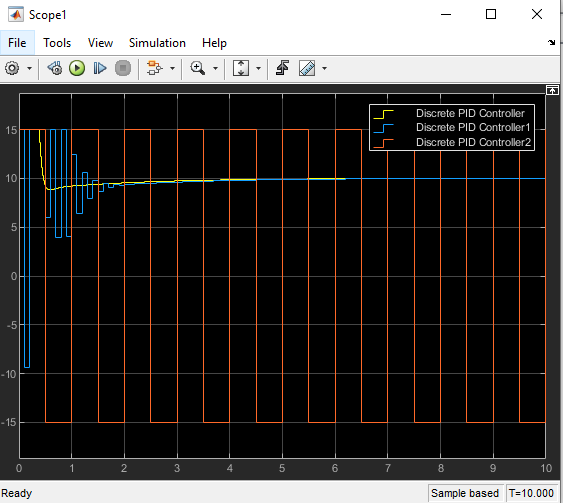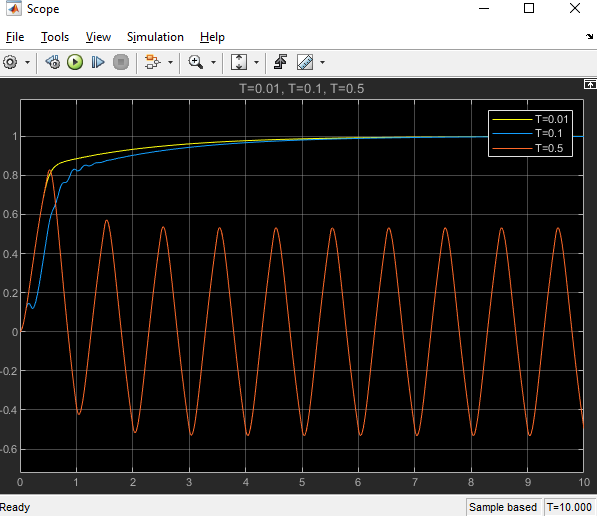

#### Tarea 3: Sintonizacion experimental (Ziegler Nichols)

La función de transferencia de un proceso controlado mediante un PID viene dada por $G_p =\frac{40}{2s^3 +10s^2 +8s+10}$ en configuración de realimentación negativa y unitaria. 

a) Hallar la respuesta escalón del sistema en bucle cerrado con un controlador unitario en SIMULINK

% Tu código aquí

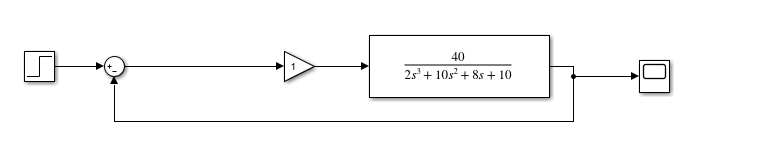

`Resultado esperado:`

b) Diseñar un controlador PID sando el segundo método de Ziegler-Nichols (oscilaciones sostenidas) (usar bloque PID) indicando como afecta el uso del controlador a la respuesta en bucle cerrado en SIMULINK.

 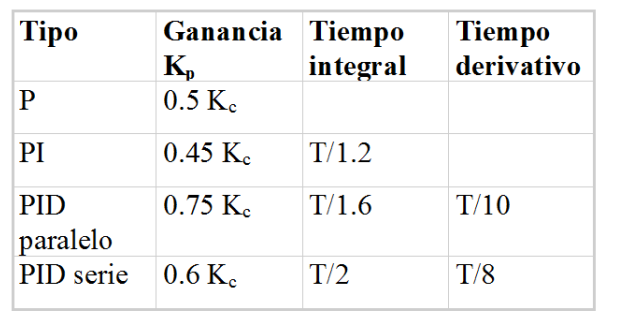

%Tu código aquí


`Resultado esperado:`

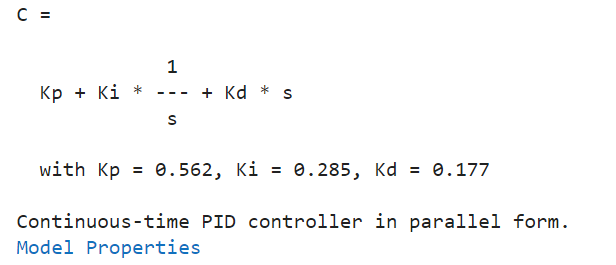

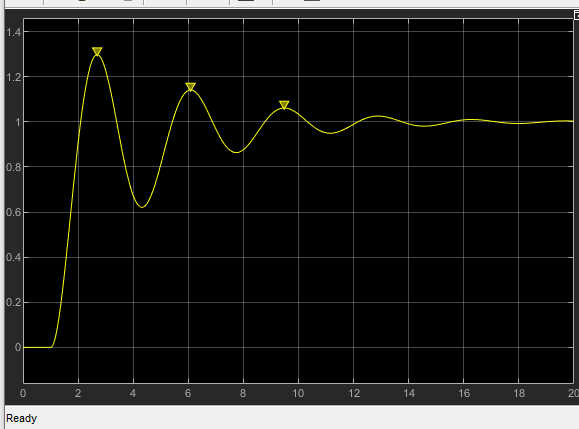

c) Proceder al reajuste manual del PID en función de la mejora de la curva de respuesta